**Physical setting**

car = [];
car.M_total = 2149;
car.g = 9.81;
car.m_wheel = 30.556;
car.r_wheel = 0.32985;
car.Cd = 0.23;
car.V_desire = 27.778;
car.wide = 1.849;
car.height = 1.443;
car.rho_air = 1.17;
car.A = car.height * car.wide;
car.Gr = 14;
car.beta = car.rho_air*car.A*car.Cd/2;
car.I_wheel = 0.5*car.m_wheel*car.r_wheel^2;
motor = [];
motor.R = 3.04;
motor.L = 0.104;
motor.J = 0.06;
motor.kt = 1.86;
motor.ki = 1.86;
ieff = (2*car.I_wheel/car.r_wheel)+(motor.J*car.Gr^2/car.r_wheel)+2*car.m_wheel*car.r_wheel+(car.M_total-2*car.m_wheel)*car.r_wheel;

**Design criteria**

overshoot<10%

rise time <6s

settling time<14s

**Transfer Function**

T2V = tf(1,[ieff 2*car.beta*car.r_wheel*car.V_desire]);
T2VD = [ieff 2*car.beta*car.r_wheel*car.V_desire];
E2TD = car.r_wheel*conv([motor.L motor.R],[ieff 2*car.beta*car.r_wheel*car.V_desire])+[0 0 motor.ki*motor.kt*car.Gr^2];
E2TN = car.r_wheel*car.Gr*motor.kt*[ieff 2*car.beta*car.r_wheel*car.V_desire];
E2T = tf(E2TN,E2TD);
dragstar = 2*car.beta*car.r_wheel*car.V_desire^2;
Tstar = car.beta*car.r_wheel*car.V_desire^2;
disturb = Tstar - dragstar;
E2V = tf(motor.kt*car.Gr*car.r_wheel,E2TD);
%sisotool(E2V)

**2D Animation**

model="model3_bode_2021a.slx"

model = "model3_bode_2021a.slx"

out = sim(model);
n = length(out.tout);
ti_name=["Tuning by PID","Tuning by root locus","Tuning by Frequency response"]

ti_name = 1×3 string array
    "Tuning by PID"    "Tuning by root locus"    "Tuning by Frequency response"


file_name=["model_2021a.slx","model2_2021a.slx","model3_bode_2021a.slx"]

file_name = 1×3 string array
    "model_2021a.slx"    "model2_2021a.slx"    "model3_bode_2021a.slx"


i = 1;
t0 = 0;
cla;
car_displace = interp1(linspace(out.tout(1),out.tout(end),length(out.displace)),out.displace,out.tout,"spline")

car_displace =          0
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0003


car_velocity = interp1(linspace(out.tout(1),out.tout(end),length(out.velocity)),out.velocity,out.tout,"spline")

car_velocity =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0002
    0.0014
    0.0088
    0.0246


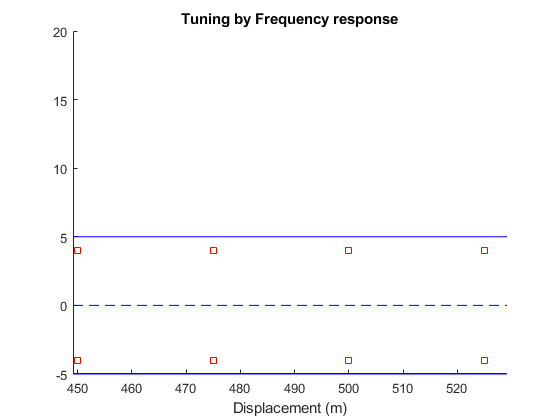

hold on
plot(0:25:1000,ones(41)*4,"s", 'Color',"r")
plot(0:25:1000,ones(41)*-4,"s", 'Color',"r")
plot([0 1000], [5 5], 'Color', 'blue')
plot([0 1000], [0 0],'--', 'Color', 'blue')
plot([0 1000], [-5 -5], 'Color', 'blue')
xlabel("Displacement (m)")
title(ti_name(file_name==model))
for t = 0:1:(n-1)
    x_car = car_displace(i);
    p_car_up = plot(linspace(x_car-4,x_car+4,10),ones(10),"b-");
    p_car_down = plot(linspace(x_car-4,x_car+4,10),ones(10)*-1,"b-");
    p_car_left = plot(ones(10)*(x_car-4),linspace(-1,1,10),"b-");
    p_car_right = plot(ones(10)*(x_car+4),linspace(-1,1,10),"b-");
    p_center = plot(x_car,0,"bo");
    disp_vel = text(x_car+20,15,num2str("v = "+car_velocity(i))+" m/s");
    disp_t = text(x_car+20,17,num2str("t = "+out.tout(i))+" s");
    axis([x_car-40 x_car+40 -5 20])
    tdiff = out.tout(i) - t0;
    t0 = out.tout(i);
    pause(tdiff)
    i = i + 1;
    delete(disp_vel)
    delete(disp_t)
    delete(p_center)
    delete(p_car_up)
    delete(p_car_down)
    delete(p_car_left)
    delete(p_car_right)
end
hold off

**time respond **

plot(out.tout,car_velocity)
yss=27.778

yss = 27.7780

settling_v=yss*1.01;
steady_state_error=abs(car.V_desire-yss)*100/car.V_desire;
overshoot=abs(max(car_velocity)-car_velocity(end))*100/car_velocity(end);
ylabel('car velocity (m/s)')
xlabel('time (second)')
v_10=car_velocity(end)*0.1;
v_90=car_velocity(end)*0.9;
[value,ir]=min(abs(settling_v-car_velocity));
[value2,ir2]=min(abs(v_10-car_velocity));
[value3,ir3]=min(abs(v_90-car_velocity));
settling_time=out.tout(ir);
rise_time=out.tout(ir3)-out.tout(ir2);
text(13,25,"settling time "+num2str(settling_time)+" s")
text(13,19,"rise time "+num2str(rise_time)+" s")
text(13,27,"%MP "+num2str(overshoot)+"%")
text(13,23,"yss "+num2str(yss)+" m/s")
text(13,21,"ess "+num2str(steady_state_error)+"%")
ti_name2=["Time respond by PID tuning","Time respond by root locus tuning","Time respond by frequency respond tuning"]

ti_name2 = 1×3 string array
    "Time respond by PID tuning"    "Time respond by root locus tuning"    "Time respond by frequency respond tuning"


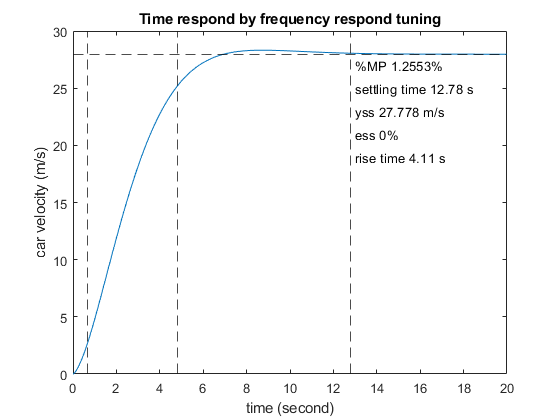

title(ti_name2(file_name==model))
xline(out.tout(ir2),"k--")
xline(out.tout(ir3),"k--")
xline(out.tout(ir),"k--")
yline(yss,"k--")
xlim([0 20])
ylim([0 30])